% Add functions path
addpath('Functions\')

% Algorithm parameters
MAX_ITERATIONS  = 20000;
q1s             = [0.7, 0.8, 0.9];
beta            = 0.05;
q0s             = [0.3, 0.4, 0.5];

% Matrix Setup
[m,n,A,x,b] = SystemSetup(3000,500,"gaussian",beta);

% Graph Parameters 
% xpoints and graphstep serve to only display every graphstep-th point of the graph
graphstep       = 100;
xpoints         = 1:graphstep:MAX_ITERATIONS+1;

errgraph = figure;
set(gca, 'YScale', 'log')
hold on

i = 1

i = 1

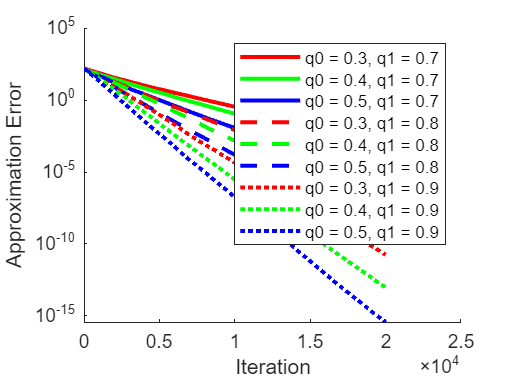

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


list_of_plot_types = ["-r" "-g" "-b" "--r" "--g" "--b" ":r" ":g" ":b"];

% Run and plot the squared error vs iteration of dqRK for the range of lower/upper quantiles 
for q1 = q1s
    for q0 = q0s
        
        % Initialization
        xk  = zeros(n, 1);

        % Data collection values
        derr    = zeros(MAX_ITERATIONS+1, 1);
        derr(1)     = norm(x - xk)^2;

        % Run dqRK for MAX_ITERATIONS
        for iter = 1:MAX_ITERATIONS
            xk        = dqRKalgstep(A,xk,b,q0,q1);

            %   Data collection
            derr(iter + 1)  = norm(x-xk)^2;
        end
        
        % Plot error graph for this run of dqRK
        semilogy(xpoints, derr(xpoints),list_of_plot_types(i),'DisplayName',"q0 = " + q0 + ", q1 = " + q1,'LineWidth', 2);
        i = i + 1;
    end
end


xlabel("Iteration")
ylabel("Approximation Error")
legend
hold off

% Save tikz plot
filename = "Figs\dqRK_vary_quantiles";
saveas(errgraph, filename, 'fig');
filename = convertStringsToChars(filename+".tex");
matlab2tikz(filename)